problem 1-part 1

initialize the parameters 

% Define your parameters
theta = [0.3, -0.5, 0.5, 0.2, 0.4];
u_mean = 1;
u_std = 0.12;

% Initialize a matrix to store all the Y values
Y_all = zeros(100, 100);


% Generate half of u values from N(u_mean, u_std)
half_size = 100/2;
u_half1 = -u_mean + sqrt(u_std) * randn(half_size, 1);

% Generate half of u values from N(-u_mean, u_std)
u_half2 = u_mean + sqrt(u_std) * randn(half_size, 1);
u = [u_half1; u_half2];

% Generate X matrix
X = [ones(100,1), u, u.^2/2, u.^3/3, u.^4/4];

create Y_all 100*100 matrix based on X


for i = 1:100  %for part 2 make this 1000
    % Generate noise N(mu, sigma)
    N = randn(100, 1);

    % Calculate Y
    Y = X * theta' + N;
    
    % Store Y in the matrix
    Y_all(:, i) = Y;
end

Least sqaure method

% Perform LS estimation 
theta_hat_LS = (X' * X)^-1 * X' * Y_all;

Weighted Least square method

% Perform WLS estimation
% You need to define Q matrix for WLS
Q = diag(rand(100,1)); % For example, identity matrix
theta_hat_WLS = inv(X' * Q * X) * X' * Q * Y_all;

calculated Y_hat_LS and sort it

 % Calculate Y_hat_LS
 Y_hat_LS = X * theta_hat_LS;

% Sort X
[X_sorted, idx] = sort(X(:, 2)); % Sorting according to the second column (u)
%X_sorted = X(idx, :);
 
% Sort Y according to the indexes of sorted X
Y_sorted_LS = Y_hat_LS(idx,:);
 
% Calculate the average of each column of Y_sorted
Y_avg_LS = mean(Y_sorted_LS, 2); 

calcualte Y_hat_WLS and sort it


 % Calculate Y_hat_LS
 Y_hat_WLS = X * theta_hat_WLS;

% Sort X
% no need to sort - already done in prevous block

 
% Sort Y according to the indexes of sorted X
Y_sorted_WLS = Y_hat_WLS(idx,:);
 
% Calculate the average of each column of Y_sorted
Y_avg_WLS = mean(Y_sorted_WLS, 2); 

calculate the std

% Calculate the std along columns (std of each row)
std_along_columns_LS = (std(Y_sorted_LS, 0, 2));
std_along_columns_WLS = (std(Y_sorted_WLS, 0, 2));

plot  for LS

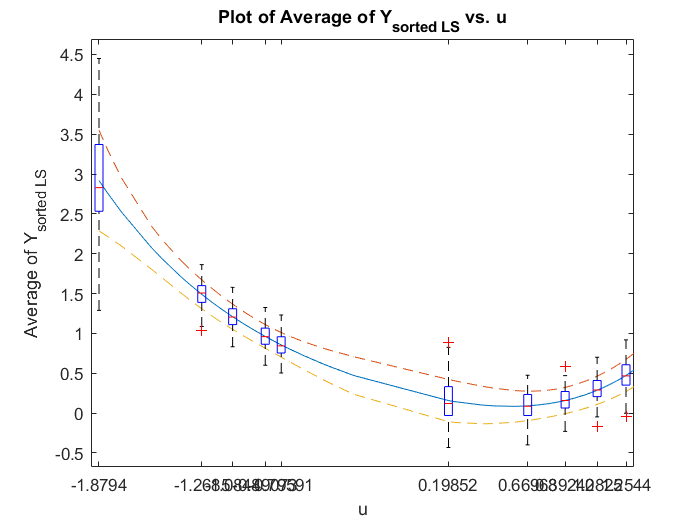

% Plot the average of Y_sorted with respect to u
figure;
plot(X_sorted, Y_avg_LS, '-');
xlabel('u');
ylabel('Average of Y_{sorted LS}');
title('Plot of Average of Y_{sorted LS} vs. u');
hold on
plot(X_sorted, Y_avg_LS + std_along_columns_LS , '--');
plot(X_sorted, Y_avg_LS - std_along_columns_LS , '--');
%scatter(u(idx, :),Y_sorted)
%errorbar(u(idx(1:10:end), :), Y_sorted(1:10), std_along_columns(1:10), 'o-');
% boxplot(Y_sorted(1:10, :).')
% xticklabels(X_sorted.');
% Create the boxplot
hBoxPlot = boxplot(Y_sorted_LS(1:10:100, :).', 'Positions', X_sorted(1:10:100));

% Set the x-tick labels to correspond to the sorted X values
set(gca, 'xticklabel', arrayfun(@num2str, X_sorted(1:10:100), 'UniformOutput', false));

%xticks(X_sorted(1:10, :));
hold off

plot for WLS

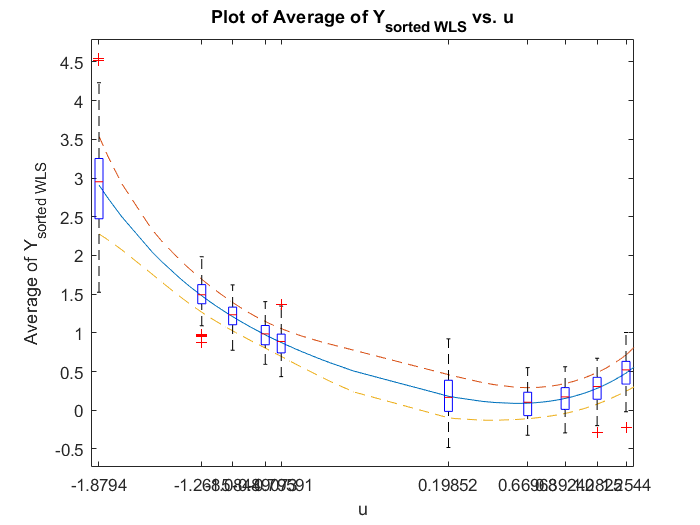

% Plot the average of Y_sorted with respect to u
figure;
plot(X_sorted, Y_avg_WLS, '-');
xlabel('u');
ylabel('Average of Y_{sorted WLS}');
title('Plot of Average of Y_{sorted WLS} vs. u');
hold on
plot(X_sorted, Y_avg_WLS + std_along_columns_WLS , '--');
plot(X_sorted, Y_avg_WLS - std_along_columns_WLS , '--');
%scatter(u(idx, :),Y_sorted)
%errorbar(u(idx(1:10:end), :), Y_sorted(1:10), std_along_columns(1:10), 'o-');
% boxplot(Y_sorted(1:10, :).')
% xticklabels(X_sorted.');
% Create the boxplot
hBoxPlot = boxplot(Y_sorted_WLS(1:10:100, :).', 'Positions', X_sorted(1:10:100));

% Set the x-tick labels to correspond to the sorted X values
set(gca, 'xticklabel', arrayfun(@num2str, X_sorted(1:10:100), 'UniformOutput', false));

%xticks(X_sorted(1:10, :));
hold off

test for Y_sorted

% Y_sorted
% Y_sorted(1:10)
% Y_sorted(1:10, :)
%Y_sorted(1:10, :).'
%Y_sorted(3, :).'

test for X_sorted

%X_sorted
%X_sorted(1:10, :)

problem 1-part 2

plot CI for LS 

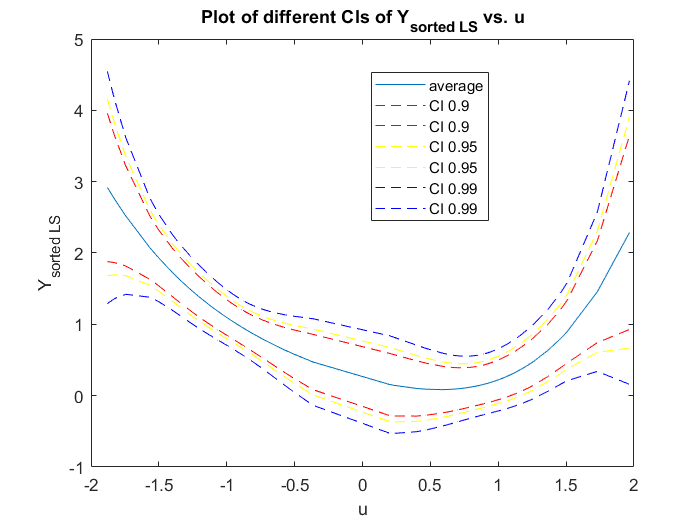

% Calculate confidence intervals for 90%, 95%, and 99%
alpha = [0.1, 0.05, 0.01];
colors = {'red','yellow','blue'};
figure; 
plot(X_sorted, Y_avg_LS, '-','DisplayName',"average");
xlabel('u');
ylabel('Y_{sorted LS}');
title('Plot of different CIs of Y_{sorted LS} vs. u');
hold on
for i = 1:length(alpha)
    z = abs(norminv(alpha(i)/2));
    CI_LS = z * std_along_columns_LS;
    
    % Use the same color for upper and lower CI plots
    color = colors{i};
    
    plot(X_sorted, Y_avg_LS + CI_LS , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))], 'Color', color);
    plot(X_sorted, Y_avg_LS - CI_LS , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))], 'Color', color);
end
legend('Location', 'best');
hold off

plot CI for WLS

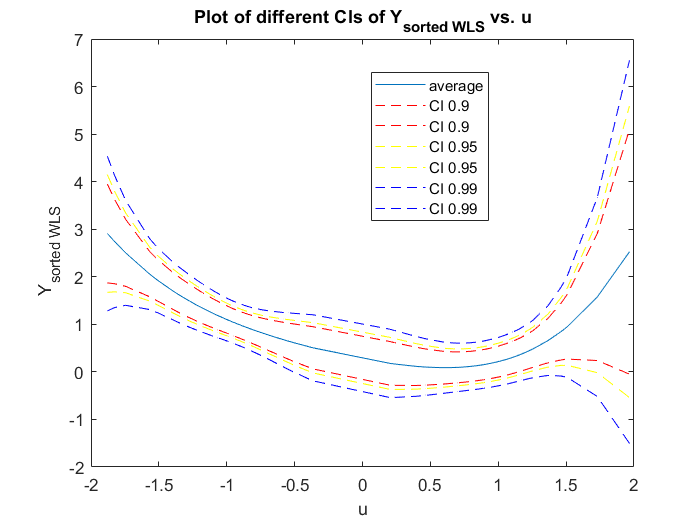

% Calculate confidence intervals for 90%, 95%, and 99%
alpha = [0.1, 0.05, 0.01];
colors = {'red','yellow','blue'};
figure; 
plot(X_sorted, Y_avg_WLS, '-','DisplayName',"average");
xlabel('u');
ylabel(' Y_{sorted WLS}');
title('Plot of different CIs of Y_{sorted WLS} vs. u');
hold on
for i = 1:length(alpha)
    z = abs(norminv(alpha(i)/2));
    CI_WLS = z * std_along_columns_WLS;
    
    % Use the same color for upper and lower CI plots
    color = colors{i};
    
    plot(X_sorted, Y_avg_WLS + CI_WLS , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))], 'Color', color);
    plot(X_sorted, Y_avg_WLS - CI_WLS , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))], 'Color', color);
end
legend('Location', 'best');
hold off

problem 1 - part 3

box plot and histogram for LS

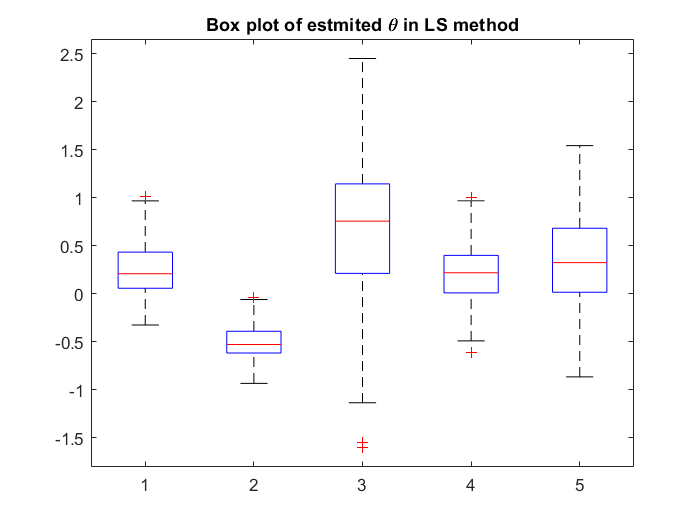

figure();
boxplot(theta_hat_LS');
title('Box plot of estmited \theta in LS method');
hold off

for i=1:5
subplot(2,3,i)
histogram(theta_hat_LS(i,:))
ylabel('Frequency')
xlabel(['Parameter ' num2str(i)])
end
title(' Histogram of Estimated Parameters in LS method')
hold off

box plot and histogram for WLS

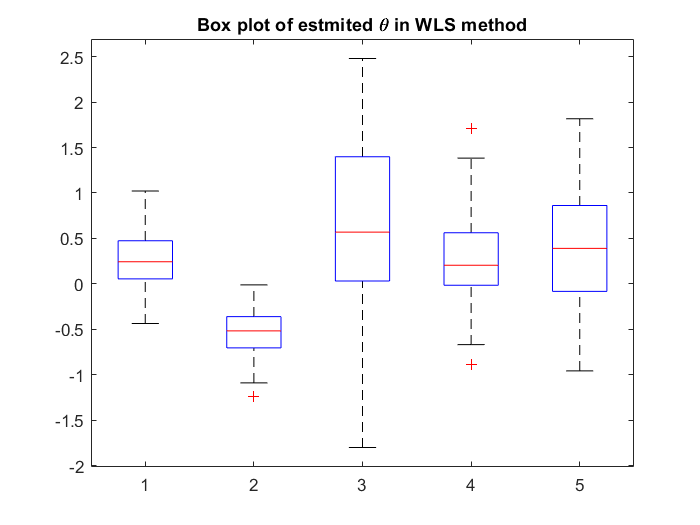

figure();
boxplot(theta_hat_WLS');
title('Box plot of estmited \theta in WLS method');
hold off

for i=1:5
subplot(2,3,i)
histogram(theta_hat_WLS(i,:))
ylabel('Frequency')
xlabel(['Parameter ' num2str(i)])
end
title(' Histogram of Estimated Parameters in WLS method')
hold off

prblem 1 - part 4

calculating ER for each LS and WLS methods

ER_WLS = zeros(5,100);      %to store all the estimation errors with WLS method
ER_LS = zeros(5,100);       %to store all the estimation errors with LS method

for j = 1:5
    for i = 1:100
       ER_WLS(j,i) = (abs(theta(j)-theta_hat_WLS(j,i)))/(abs(theta(j))); 
       ER_LS(j,i) = (abs(theta(j)-theta_hat_LS(j,i)))/(abs(theta(j)));        
    end
end

plot the ERs

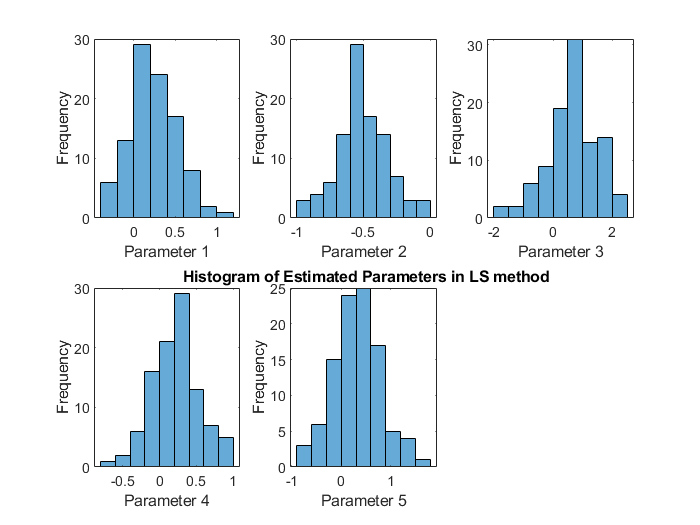

figure();
boxplot(ER_LS');

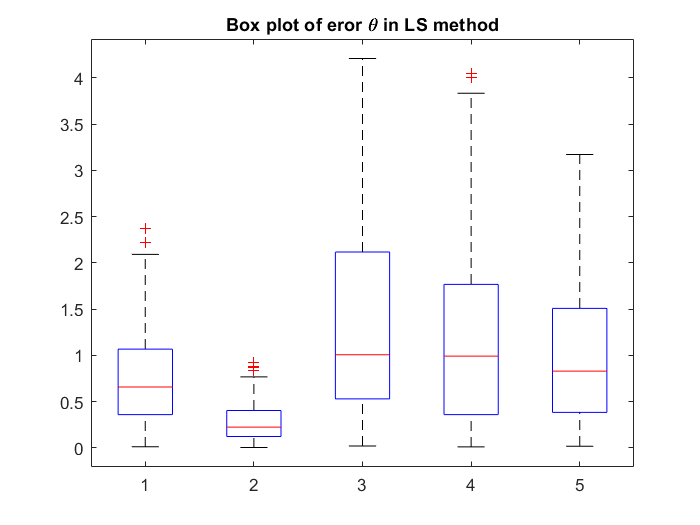

title('Box plot of eror \theta in LS method');
hold off

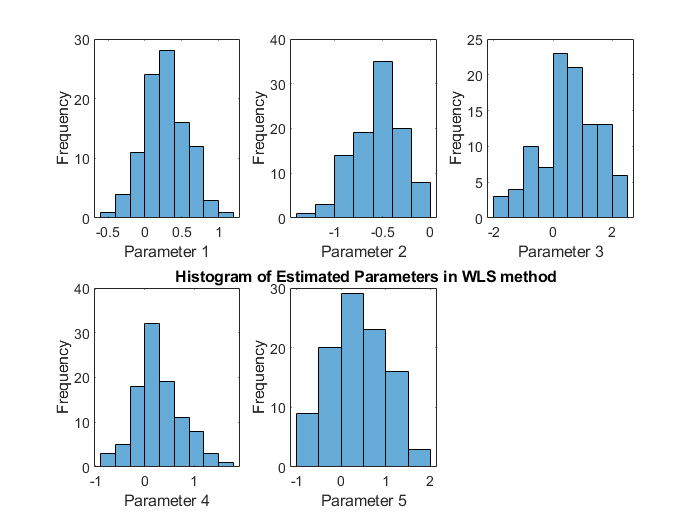


figure();
boxplot(ER_WLS');

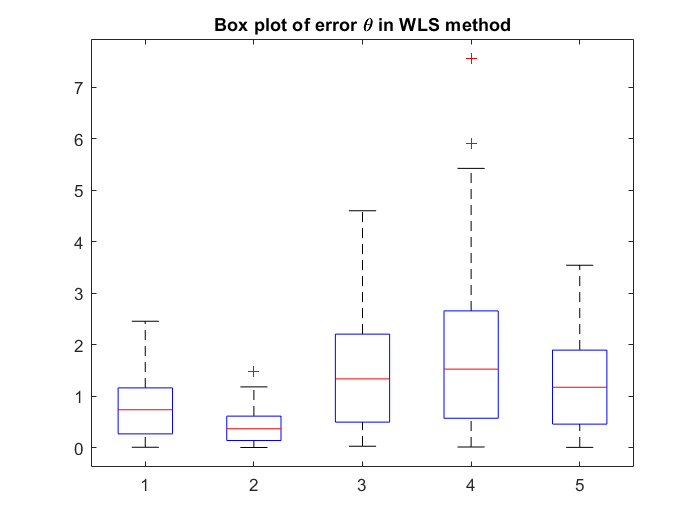

title('Box plot of error \theta in WLS method');
hold off